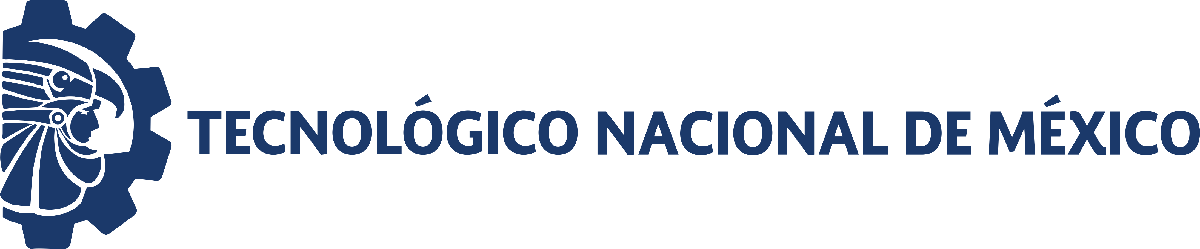                                 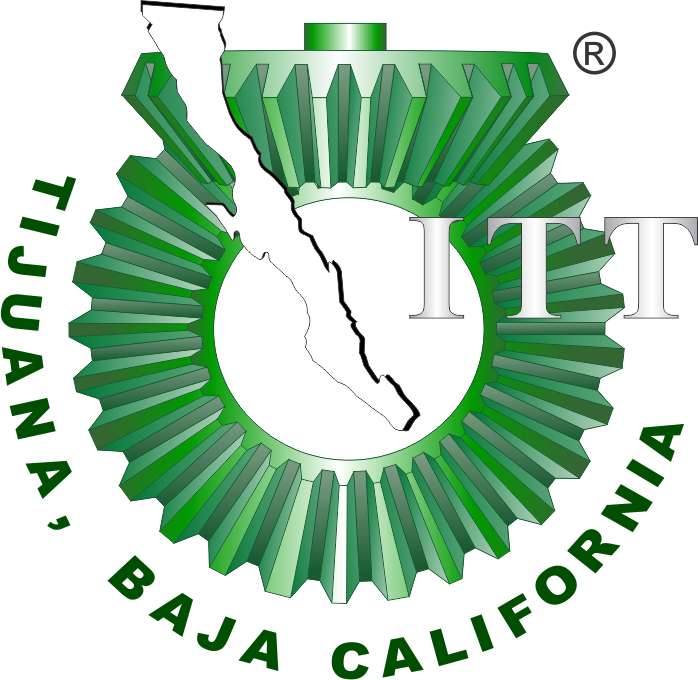

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 2: Caos en sistemas biológicos

## Información general

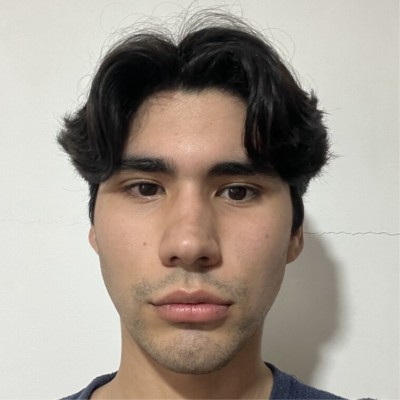

Nombre del alumno: **Alberto Villalobos Valdez**

Número de control: **22212277**

Correo institucional: **L22212277@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Descripción

Comparar métodos de diferencias finitas para solucionar sistemas de ODEs no lineales de primer orden que exhiben diferentes conjuntos compactos invariantes para diferentes valores en sus parámetros y/o condiciones iniciales. El modelo matemático está compuesto por las siguientes tres EDOs de primer orden:


$$\dot x = r_1 x (1-b_1x)-a_{12}xy-a_{13}xz
$$



$$\dot y = r_2y(1-b_2y)-a_{21}xy$$



$$\dot z = (r_3-a_{31})xz-d_3z+\rho_i$$


donde la variable de estado $x\left(t\right)$ representa la población de células anormales o patalógicas, la variable de estado $y\left(t\right)$ la población de células normales o sanas y la variable de estado $z\left(t\right)$ población de células efectoras (citotóxicas o NK); la descripción y valores de los parámetros se presenta a continuación:

$r_1 =1:$ Tasa de crecimiento de las células patológicas.

$b_1 =1:$ Capacidad de carga máxima de las células patológicas.

$a_{12} \in \left\lbrack 0,1\right\rbrack :$ Fracción de células patológicas eliminadas por las células sanas.

$a_{13} =2\ldotp 5:$ Fracción de células patológicas eliminadas por células efectoras.

$r_2 =0\ldotp 6:$ Tasa de crecimiento de las células sanas.

$b_2 =1:$ Capacidad de carga máxima de las células sanas.

$a_{21} =1\ldotp 5:$ Fracción de células sanas eliminadas por las células patológicas.

$r_3 =3:$ Tasa de reclutamiento máximo de células efectoras.

$a_{31} =0\ldotp 3:$ Fracción de células efectoras inactivadas por las células patológicas.

$d_3 =0\ldotp 4:$ Tasa de muerte de las células efectoras.

$\rho_i \left(t\right):$ Tratamiento de inmunoterapia.

Cabe destacar que la dinámica del sistema se localiza en octante no negativo definido por el siguiente dominio:


$$\mathbf{R}_{+,0}^{3}=\left\{ x\left( t\right) \geq 0,y\left( t\right) \geq 0,z\left( t\right) \geq 0\right\}$$


El sistema exhibe diferentes dinámicas para distintos valores del parámetro de bifurcación $a_{12}$, como se indica a continuación:

- Un atractor caótico con $a_{12} =1$, en el intervalo de tiempo $t\in \left\lbrack 0,1000\right\rbrack$ y las condiciones iniciales:$\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 555,0\ldotp 148,0\ldotp 172\right)\ldotp$

- Una órbita periódica con $a_{12} =0\ldotp 9$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 254781,0\ldotp 115167,0\ldotp 600527\right)\ldotp$

- Un ciclo límite interno con $a_{12} =0\ldotp 8$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 2,0\ldotp 6,0\ldotp 1\right)\ldotp$

- Un ciclo límite externo con $a_{12} =0\ldotp 75$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 4,0\ldotp 2,0\ldotp 4\right)\ldotp$

- Convergencia hacia un punto de equilibrio con $a_{12} =0\ldotp 5$, en el intervalo de tiempo $t\in \left\lbrack 0,500\right\rbrack$ y las condiciones iniciales: $\left(x\left(0\right),y\left(0\right),z\left(0\right)\right)=\left(0\ldotp 5,0\ldotp 5,0\ldotp 4\right)\ldotp$

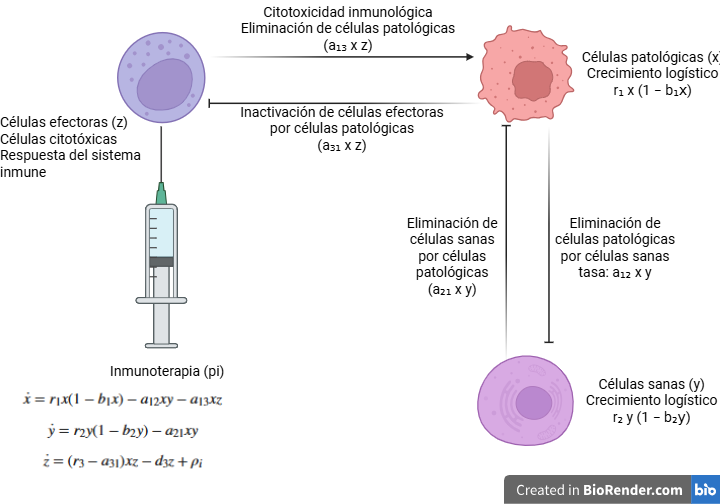

Figura. Representacion del sistema

## Referencias

[1] Valle, Paul A., *Syllabus para Biología de Sistemas y Gemelos Digitales*, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Itik, M., & Banks, S. P. (2010). Chaos in a three-dimensional cancer model. *international Journal of bifurcation and chaos*, *20*(01), 71-79. [https://doi.org/10.1142/S0218127410025417](https://doi.org/10.1142/S0218127410025417)

[3] Bryan, Kurt. *Differential equations: A toolbox for modeling the world*. Simiode, 2022. Permalink: [https://www.simiode.org/resources/8307](https://www.simiode.org/resources/8307) 

tic; clc; clear; close all

## Puntos de equilibrio

syms x y z
syms r1 b1 a12 a13
syms r2 b2 a21
syms r3 a31 d3 rhoi
dx_dt = r1*x*(1 - b1*x) - a12*x*y - a13*x*z == 0;
dy_dt = r2*y*(1 - b2*y) - a21*x*y == 0;
dz_dt = (r3 - a31)*x*z - d3*z + rhoi == 0;
E = solve([dx_dt,dy_dt,dz_dt],[x,y,z]);
fprintf(['Puntos de equilibrio del sistema: ', num2str(length(E.x))]);

Puntos de equilibrio del sistema: 6

for i = 1:6
    disp([E.x(i);E.y(i);E.z(i)])
end

$$\begin{array}{l} \left(\begin{array}{c} \frac{r_{1}-\frac{a_{13}\,\sigma_{1}}{2\,\left(a_{13}\,a_{31}-a_{13}\,r_{3}\right)}}{b_{1}\,r_{1}}\\ 0\\ \frac{\sigma_{1}}{2\,\left(a_{13}\,a_{31}-a_{13}\,r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{31}\,r_{1}-r_{1}\,r_{3}-\sqrt{r_{1}\,\left(r_{1}\,{a_{31}}^{2}+2\,r_{1}\,a_{31}\,b_{1}\,d_{3}-4\,a_{13}\,\mathrm{rhoi}\,a_{31}\,b_{1}-2\,r_{1}\,a_{31}\,r_{3}+r_{1}\,{b_{1}}^{2}\,{d_{3}}^{2}-2\,r_{1}\,b_{1}\,d_{3}\,r_{3}+4\,a_{13}\,\mathrm{rhoi}\,b_{1}\,r_{3}+r_{1}\,{r_{3}}^{2}\right)}+b_{1}\,d_{3}\,r_{1} \end{array}$$

$$\begin{array}{l} \left(\begin{array}{c} \frac{r_{2}\,\left(a_{12}-b_{2}\,r_{1}\right)}{\sigma_{2}}-\frac{\sigma_{1}}{2\,\sigma_{2}\,\left(a_{31}-r_{3}\right)}\\ \frac{a_{21}\,r_{1}-b_{1}\,r_{1}\,r_{2}}{\sigma_{2}}+\frac{a_{21}\,\sigma_{1}}{2\,b_{2}\,r_{2}\,\sigma_{2}\,\left(a_{31}-r_{3}\right)}\\ -\frac{\sigma_{1}}{2\,a_{13}\,b_{2}\,r_{2}\,\left(a_{31}-r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{a_{12}}^{2}\,{a_{21}}^{2}\,{d_{3}}^{2}+2\,{a_{12}}^{2}\,a_{21}\,a_{31}\,d_{3}\,r_{2}-2\,{a_{12}}^{2}\,a_{21}\,d_{3}\,r_{2}\,r_{3}+{a_{12}}^{2}\,{a_{31}}^{2}\,{r_{2}}^{2}-2\,{a_{12}}^{2}\,a_{31}\,{r_{2}}^{2}\,r_{3}+{a_{12}}^{2}\,{r_{2}}^{2}\,{r_{3}}^{2}-2\,a_{12}\,a_{21}\,a_{31}\,b_{2}\,d_{3}\,r_{1}\,r_{2}+4\,a_{13}\,\mathrm{rhoi}\,a_{12}\,a_{21}\,a_{31}\,b_{2}\,r_{2}-2\,a_{12}\,a_{21}\,b_{1}\,b_{2}\,{d_{3}}^{2}\,r_{1}\,r_{2}+2\,a_{12}\,a_{21}\,b_{2}\,d_{3}\,r_{1}\,r_{2}\,r_{3}-4\,a_{13}\,\mathrm{rhoi}\,a_{12}\,a_{21}\,b_{2}\,r_{2}\,r_{3}-2\,a_{12}\,{a_{31}}^{2}\,b_{2}\,r_{1}\,{r_{2}}^{2}-2\,a_{12}\,a_{31}\,b_{1}\,b_{2}\,d_{3}\,r_{1}\,{r_{2}}^{2}+4\,a_{12}\,a_{31}\,b_{2}\,r_{1}\,{r_{2}}^{2}\,r_{3}+2\,a_{12}\,b_{1}\,b_{2}\,d_{3}\,r_{1}\,{r_{2}}^{2}\,r_{3}-2\,a_{12}\,b_{2}\,r_{1}\,{r_{2}}^{2}\,{r_{3}}^{2}+{a_{31}}^{2}\,{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}+2\,a_{31}\,b_{1}\,{b_{2}}^{2}\,d_{3}\,{r_{1}}^{2}\,{r_{2}}^{2}-4\,a_{13}\,\mathrm{rhoi}\,a_{31}\,b_{1}\,{b_{2}}^{2}\,r_{1}\,{r_{2}}^{2}-2\,a_{31}\,{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}\,r_{3}+{b_{1}}^{2}\,{b_{2}}^{2}\,{d_{3}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}-2\,b_{1}\,{b_{2}}^{2}\,d_{3}\,{r_{1}}^{2}\,{r_{2}}^{2}\,r_{3}+4\,a_{13}\,\mathrm{rhoi}\,b_{1}\,{b_{2}}^{2}\,r_{1}\,{r_{2}}^{2}\,r_{3}+{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}\,{r_{3}}^{2}}+a_{12}\,a_{21}\,d_{3}+a_{12}\,a_{31}\,r_{2}-a_{12}\,r_{2}\,r_{3}-a_{31}\,b_{2}\,r_{1}\,r_{2}+b_{2}\,r_{1}\,r_{2}\,r_{3}-b_{1}\,b_{2}\,d_{3}\,r_{1}\,r_{2}\\ \sigma_{2}=a_{12}\,a_{21}-b_{1}\,b_{2}\,r_{1}\,r_{2} \end{array}$$

$$\begin{array}{l} \left(\begin{array}{c} \frac{r_{2}\,\left(a_{12}-b_{2}\,r_{1}\right)}{\sigma_{2}}+\frac{\sigma_{1}}{2\,\sigma_{2}\,\left(a_{31}-r_{3}\right)}\\ \frac{a_{21}\,r_{1}-b_{1}\,r_{1}\,r_{2}}{\sigma_{2}}-\frac{a_{21}\,\sigma_{1}}{2\,b_{2}\,r_{2}\,\sigma_{2}\,\left(a_{31}-r_{3}\right)}\\ \frac{\sigma_{1}}{2\,a_{13}\,b_{2}\,r_{2}\,\left(a_{31}-r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{a_{12}}^{2}\,{a_{21}}^{2}\,{d_{3}}^{2}+2\,{a_{12}}^{2}\,a_{21}\,a_{31}\,d_{3}\,r_{2}-2\,{a_{12}}^{2}\,a_{21}\,d_{3}\,r_{2}\,r_{3}+{a_{12}}^{2}\,{a_{31}}^{2}\,{r_{2}}^{2}-2\,{a_{12}}^{2}\,a_{31}\,{r_{2}}^{2}\,r_{3}+{a_{12}}^{2}\,{r_{2}}^{2}\,{r_{3}}^{2}-2\,a_{12}\,a_{21}\,a_{31}\,b_{2}\,d_{3}\,r_{1}\,r_{2}+4\,a_{13}\,\mathrm{rhoi}\,a_{12}\,a_{21}\,a_{31}\,b_{2}\,r_{2}-2\,a_{12}\,a_{21}\,b_{1}\,b_{2}\,{d_{3}}^{2}\,r_{1}\,r_{2}+2\,a_{12}\,a_{21}\,b_{2}\,d_{3}\,r_{1}\,r_{2}\,r_{3}-4\,a_{13}\,\mathrm{rhoi}\,a_{12}\,a_{21}\,b_{2}\,r_{2}\,r_{3}-2\,a_{12}\,{a_{31}}^{2}\,b_{2}\,r_{1}\,{r_{2}}^{2}-2\,a_{12}\,a_{31}\,b_{1}\,b_{2}\,d_{3}\,r_{1}\,{r_{2}}^{2}+4\,a_{12}\,a_{31}\,b_{2}\,r_{1}\,{r_{2}}^{2}\,r_{3}+2\,a_{12}\,b_{1}\,b_{2}\,d_{3}\,r_{1}\,{r_{2}}^{2}\,r_{3}-2\,a_{12}\,b_{2}\,r_{1}\,{r_{2}}^{2}\,{r_{3}}^{2}+{a_{31}}^{2}\,{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}+2\,a_{31}\,b_{1}\,{b_{2}}^{2}\,d_{3}\,{r_{1}}^{2}\,{r_{2}}^{2}-4\,a_{13}\,\mathrm{rhoi}\,a_{31}\,b_{1}\,{b_{2}}^{2}\,r_{1}\,{r_{2}}^{2}-2\,a_{31}\,{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}\,r_{3}+{b_{1}}^{2}\,{b_{2}}^{2}\,{d_{3}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}-2\,b_{1}\,{b_{2}}^{2}\,d_{3}\,{r_{1}}^{2}\,{r_{2}}^{2}\,r_{3}+4\,a_{13}\,\mathrm{rhoi}\,b_{1}\,{b_{2}}^{2}\,r_{1}\,{r_{2}}^{2}\,r_{3}+{b_{2}}^{2}\,{r_{1}}^{2}\,{r_{2}}^{2}\,{r_{3}}^{2}}-a_{12}\,a_{21}\,d_{3}-a_{12}\,a_{31}\,r_{2}+a_{12}\,r_{2}\,r_{3}+a_{31}\,b_{2}\,r_{1}\,r_{2}-b_{2}\,r_{1}\,r_{2}\,r_{3}+b_{1}\,b_{2}\,d_{3}\,r_{1}\,r_{2}\\ \sigma_{2}=a_{12}\,a_{21}-b_{1}\,b_{2}\,r_{1}\,r_{2} \end{array}$$

$$\left(\begin{array}{c} 0\\ \frac{1}{b_{2}}\\ \frac{\mathrm{rhoi}}{d_{3}} \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{c} \frac{r_{1}-\frac{a_{13}\,\sigma_{1}}{2\,\left(a_{13}\,a_{31}-a_{13}\,r_{3}\right)}}{b_{1}\,r_{1}}\\ 0\\ \frac{\sigma_{1}}{2\,\left(a_{13}\,a_{31}-a_{13}\,r_{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{31}\,r_{1}-r_{1}\,r_{3}+\sqrt{r_{1}\,\left(r_{1}\,{a_{31}}^{2}+2\,r_{1}\,a_{31}\,b_{1}\,d_{3}-4\,a_{13}\,\mathrm{rhoi}\,a_{31}\,b_{1}-2\,r_{1}\,a_{31}\,r_{3}+r_{1}\,{b_{1}}^{2}\,{d_{3}}^{2}-2\,r_{1}\,b_{1}\,d_{3}\,r_{3}+4\,a_{13}\,\mathrm{rhoi}\,b_{1}\,r_{3}+r_{1}\,{r_{3}}^{2}\right)}+b_{1}\,d_{3}\,r_{1} \end{array}$$

$$\left(\begin{array}{c} 0\\ 0\\ \frac{\mathrm{rhoi}}{d_{3}} \end{array}\right)$$

### Matriz Jacobiana

dx_dt = r1*x*(1 - b1*x) - a12*x*y - a13*x*z == 0;
dy_dt = r2*y*(1 - b2*y) - a21*x*y == 0;
dz_dt = (r3 - a31)*x*z - d3*z + rhoi == 0;

J = jacobian([dx_dt,dy_dt,dz_dt],[x,y,z]);
disp(J);

$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x=0 & -a_{12}\,x=0 & -a_{13}\,x=0\\ -a_{21}\,y=0 & -a_{21}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y=0 & 0\\ -z\,\left(a_{31}-r_{3}\right)=0 & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right)=0 \end{array}\right)$$

clc; clear; close all; warning('off')

## Comparación de métodos numéricos: Atractor caótico

D = getdataa('chaos'); f0 = D.f0; par = D.par;
dt = 1E-3; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 8.889e-02)
eq3        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable  
eq2         -6.1e-01+0.0e+00i  +4.1e-02+2.3e-01i  +4.1e-02-2.3e-01i  unstable  
eq3         -6.0e-01+0.0e+00i  +0.0e+00+0.0e+00i  -4.0e-01+0.0e+00i  unidentified
eq4         -6.0e-01+0.0e+00i  +0.0e+00+0.0e+00i  -4.0e-01+0.0e+00i  unidentified
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e+00

### Euler

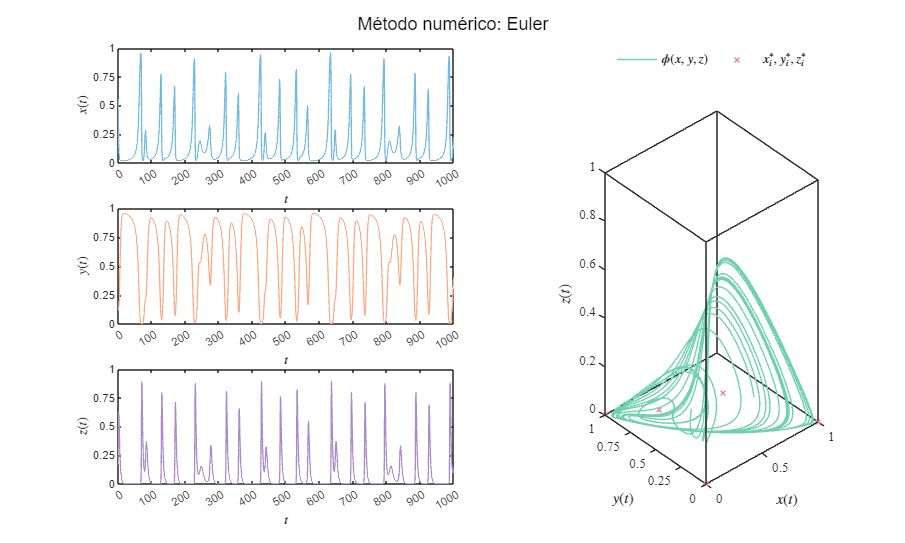

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xe,ye,ze,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Chaos.pdf'],'ContentType','vector')

### Heun

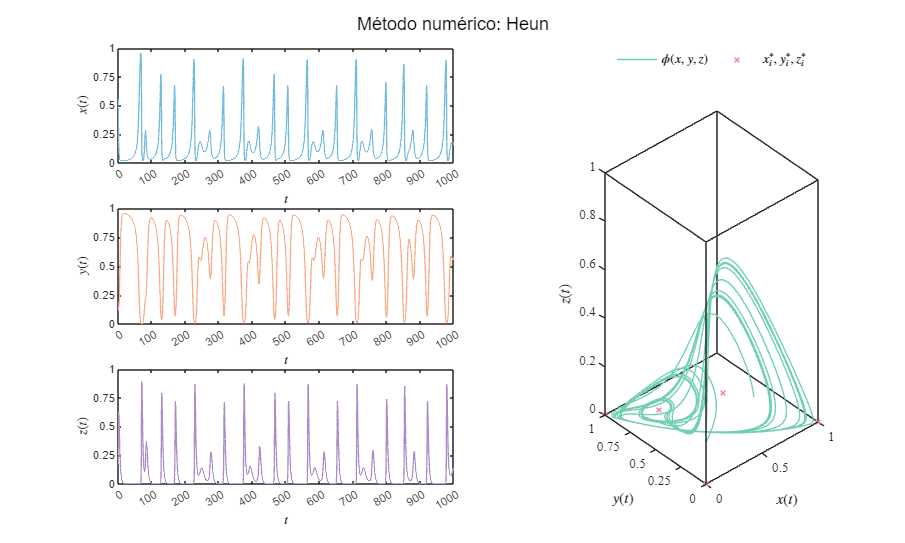

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xh,yh,zh,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Chaos.pdf'],'ContentType','vector')

### Runge-Kutta

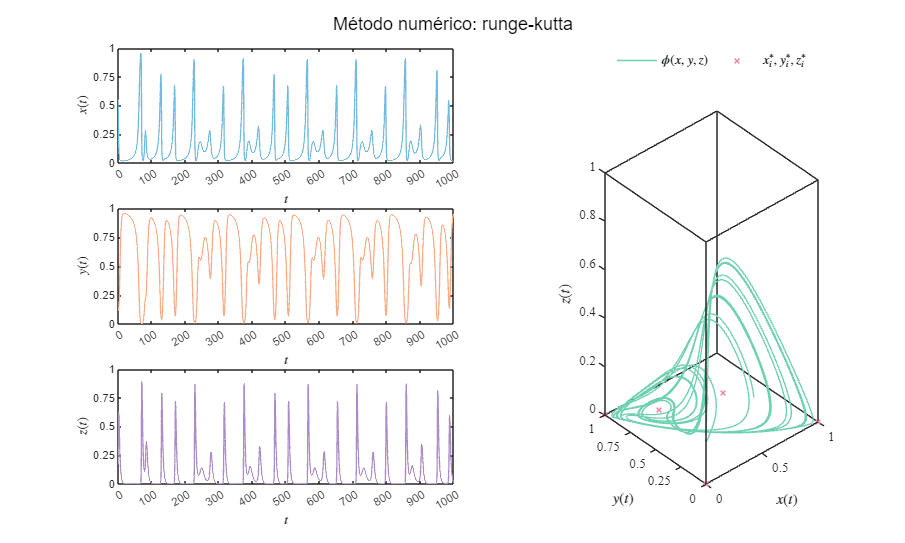

method = 'runge-kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xr,yr,zr,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Chaos.pdf'],'ContentType','vector')

### Comparación entre soluciones

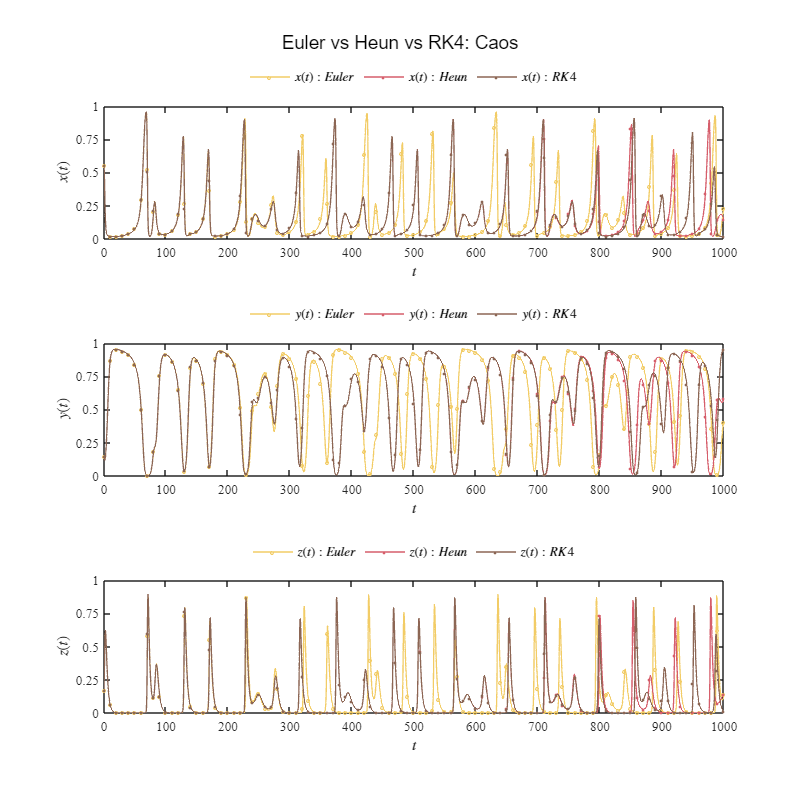

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Caos');...
    exportgraphics(gcf,'Solutions_Chaos.pdf','ContentType','vector')

### Error entre soluciones

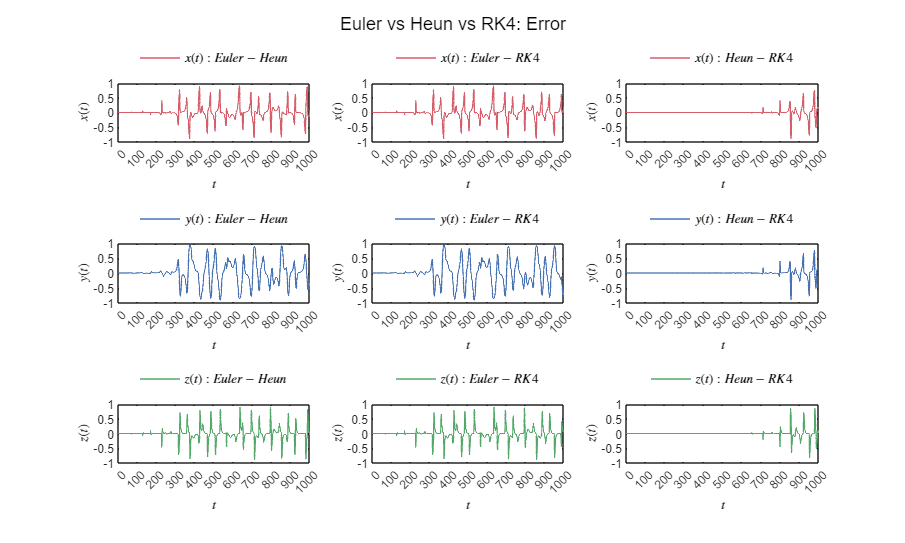

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Error');...
    exportgraphics(gcf,'Error_Caos.pdf','ContentType','vector')

## Comparación de métodos numéricos: Órbita

D = getdataa('orbit'); f0 = D.f0; par = D.par;
dt = 1E-4; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 1.141e-01)
eq3        (-8.000e-02 , 1.200e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable  
eq2         -5.8e-01+0.0e+00i  +2.6e-02+2.7e-01i  +2.6e-02-2.7e-01i  unstable  
eq3         -1.5e-01+0.0e+00i  -4.9e-01+0.0e+00i  -6.2e-01+0.0e+00i  stable    
eq4         -6.0e-01+0.0e+00i  +1.0e-01+0.0e+00i  -4.0e-01+0.0e+00i  unstable  
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e+00i  +

fprintf('Puntos de equilibrio:\n'); disp(array2table(E))

Puntos de equilibrio:
      E1         E2         E3   
    _______    _______    _______

    0.14815          0    0.34074
    0.14815    0.62963    0.11407
      -0.08        1.2          0
          0          1          0
          1          0          0
          0          0          0



### Euler

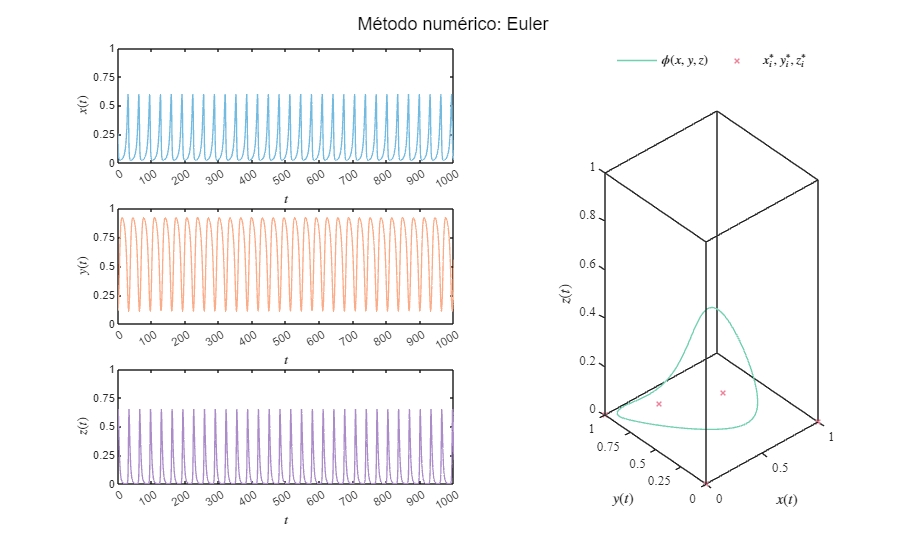

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xe,ye,ze,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Orbit.pdf'],'ContentType','vector')

### Heun

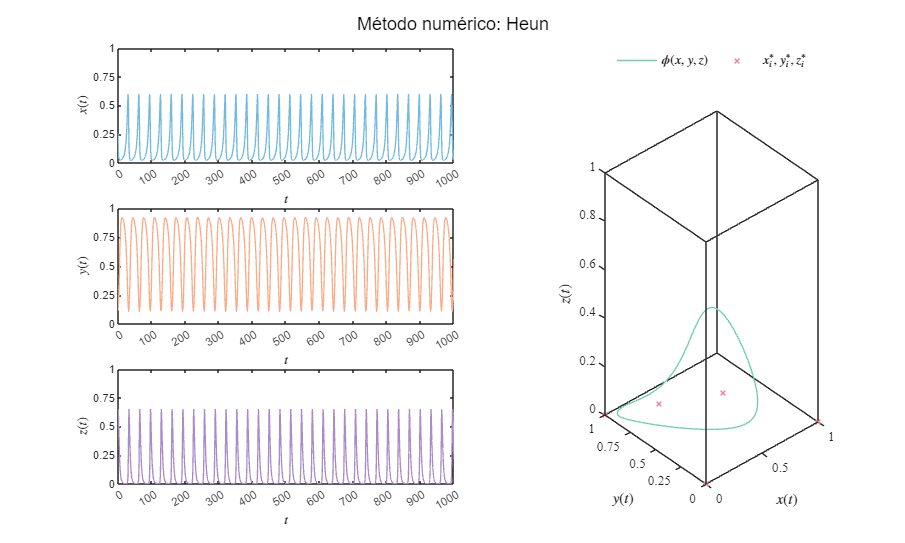

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xh,yh,zh,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Orbit.pdf'],'ContentType','vector')

### Runge-Kutta

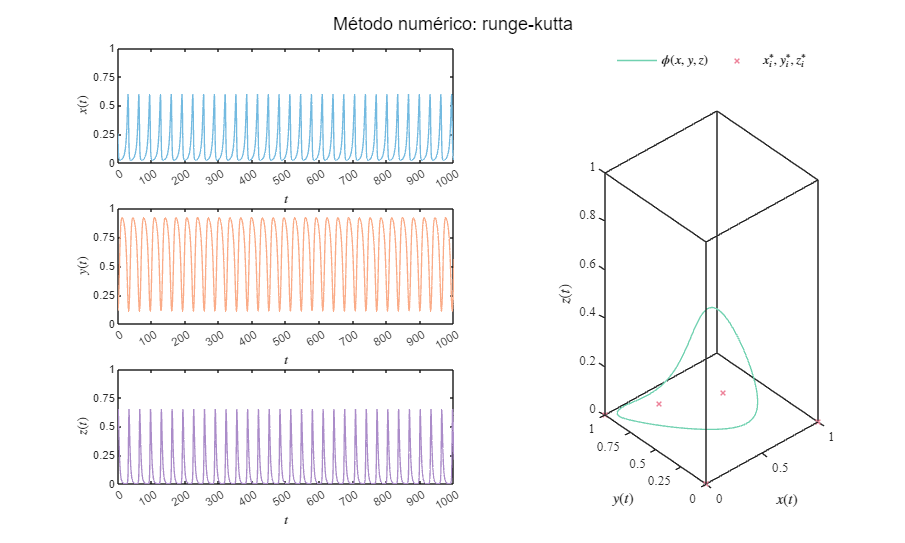

method = 'runge-kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xr,yr,zr,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Orbit.pdf'],'ContentType','vector')

### Comparación entre soluciones

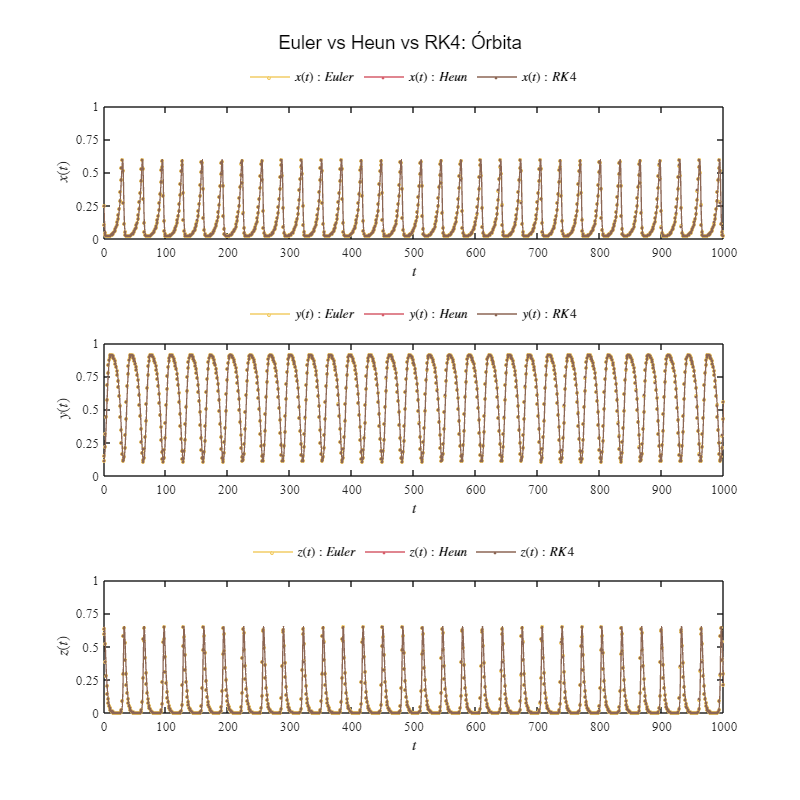

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Órbita');...
    exportgraphics(gcf,'Solutions_Orbit.pdf','ContentType','vector')

### Error entre soluciones

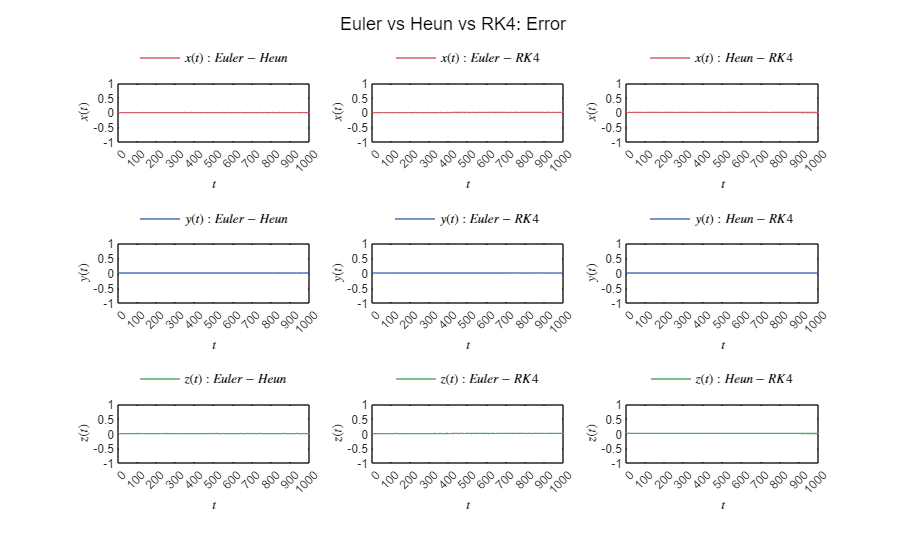

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Error');...
    exportgraphics(gcf,'Error_Orbit.pdf','ContentType','vector')

## Comparación de métodos numéricos: Ciclo 1

D = getdataa('cycle1'); f0 = D.f0; par = D.par;
dt = 1E-4; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 1.393e-01)
eq3        (-2.000e-01 , 1.500e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable  
eq2         -5.5e-01+0.0e+00i  +1.1e-02+3.1e-01i  +1.1e-02-3.1e-01i  unstable  
eq3         -3.5e-01+2.4e-01i  -3.5e-01-2.4e-01i  -9.4e-01+0.0e+00i  stable    
eq4         -6.0e-01+0.0e+00i  +2.0e-01+0.0e+00i  -4.0e-01+0.0e+00i  unstable  
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e+00i  +

fprintf('Puntos de equilibrio:\n'); disp(array2table(E))

Puntos de equilibrio:
      E1         E2         E3   
    _______    _______    _______

    0.14815          0    0.34074
    0.14815    0.62963    0.13926
       -0.2        1.5          0
          0          1          0
          1          0          0
          0          0          0



### Euler

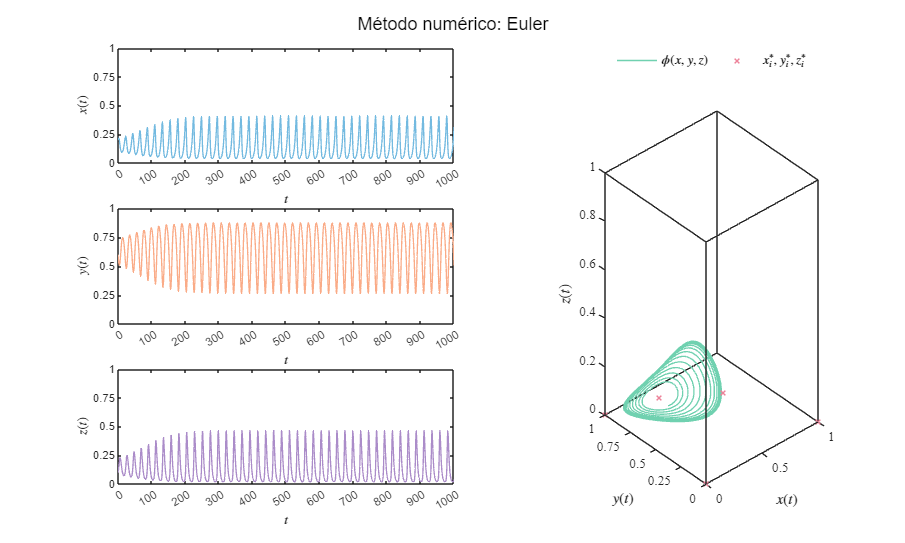

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xe,ye,ze,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Cycle1.pdf'],'ContentType','vector')

### Heun

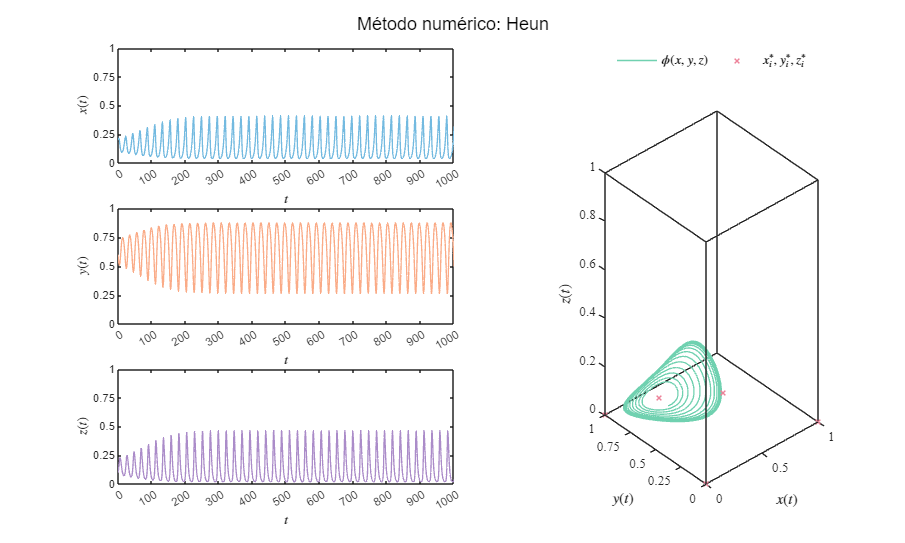

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xh,yh,zh,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Cycle1.pdf'],'ContentType','vector')

### Runge-Kutta

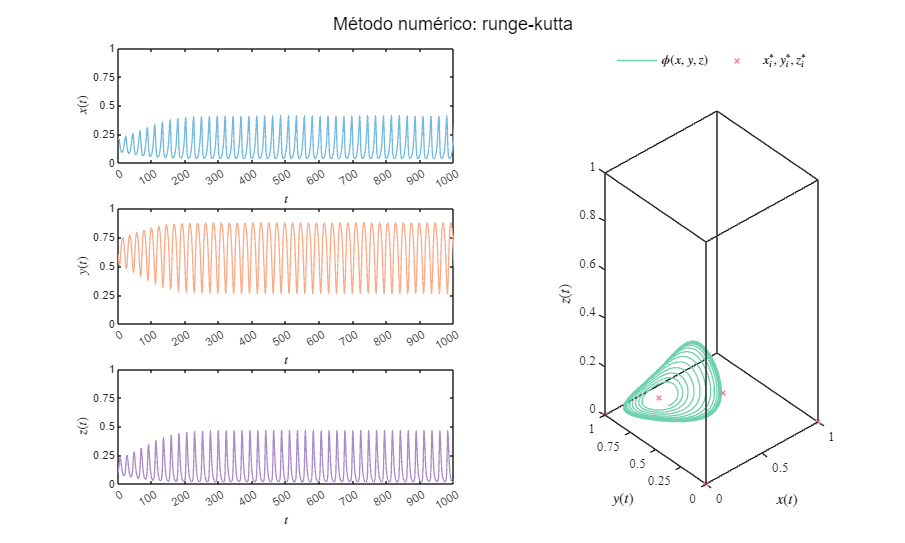

method = 'runge-kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xr,yr,zr,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Cycle1.pdf'],'ContentType','vector')

### Comparación entre soluciones

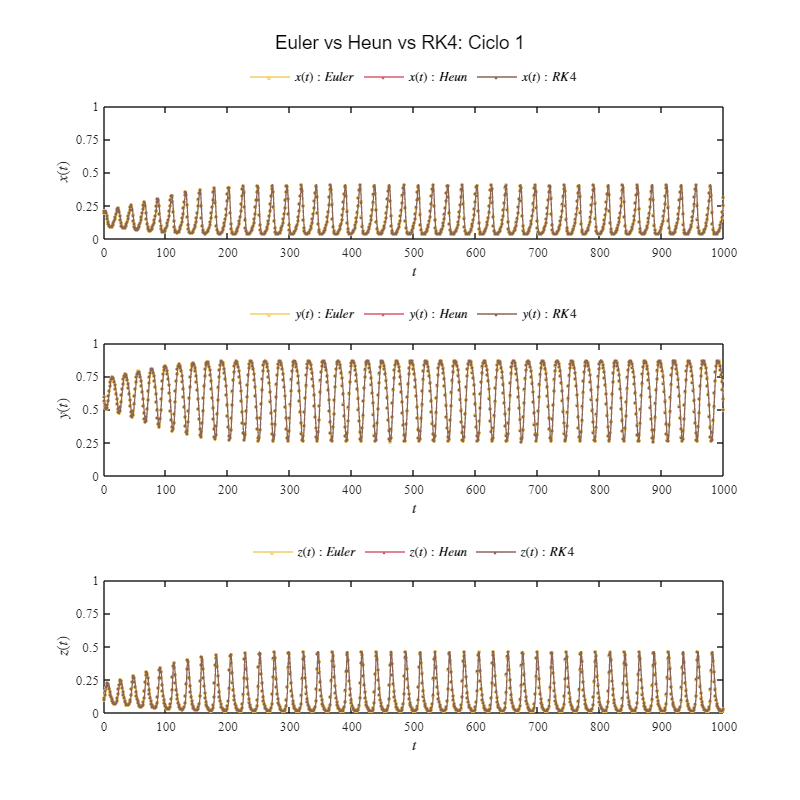

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Ciclo 1');...
    exportgraphics(gcf,'Solutions_Cycle1.pdf','ContentType','vector')

### Error entre soluciones

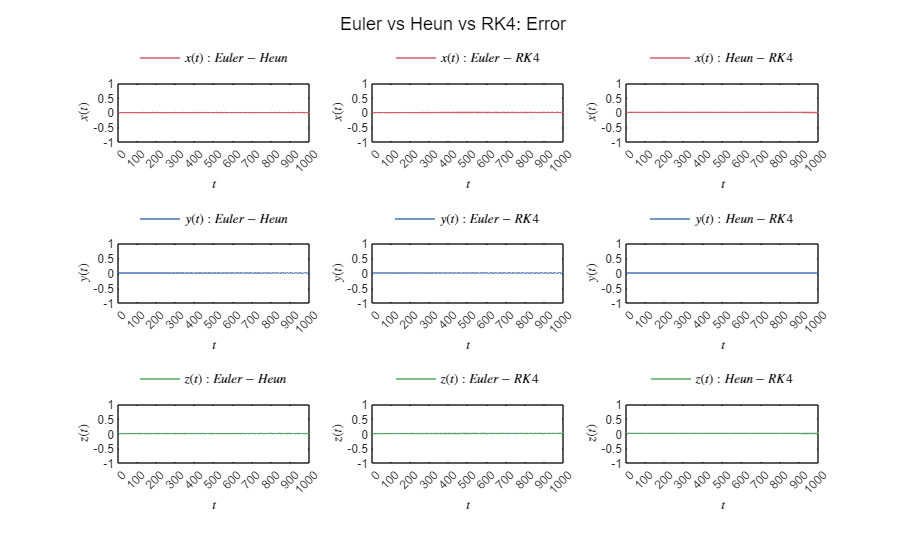

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Error');...
    exportgraphics(gcf,'Error_Cycle1.pdf','ContentType','vector')

## Comparación de métodos numéricos: Ciclo 2

D = getdataa('cycle2'); f0 = D.f0; par = D.par;
dt = 1E-4; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 1.519e-01)
eq3        (-2.857e-01 , 1.714e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable  
eq2         -5.3e-01+0.0e+00i  +4.2e-03+3.3e-01i  +4.2e-03-3.3e-01i  unstable  
eq3         -3.7e-01+3.5e-01i  -3.7e-01-3.5e-01i  -1.2e+00+0.0e+00i  stable    
eq4         -6.0e-01+0.0e+00i  +2.5e-01+0.0e+00i  -4.0e-01+0.0e+00i  unstable  
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e+00i  +

fprintf('Puntos de equilibrio:\n'); disp(array2table(E))

Puntos de equilibrio:
       E1         E2         E3   
    ________    _______    _______

     0.14815          0    0.34074
     0.14815    0.62963    0.15185
    -0.28571     1.7143          0
           0          1          0
           1          0          0
           0          0          0



### Euler

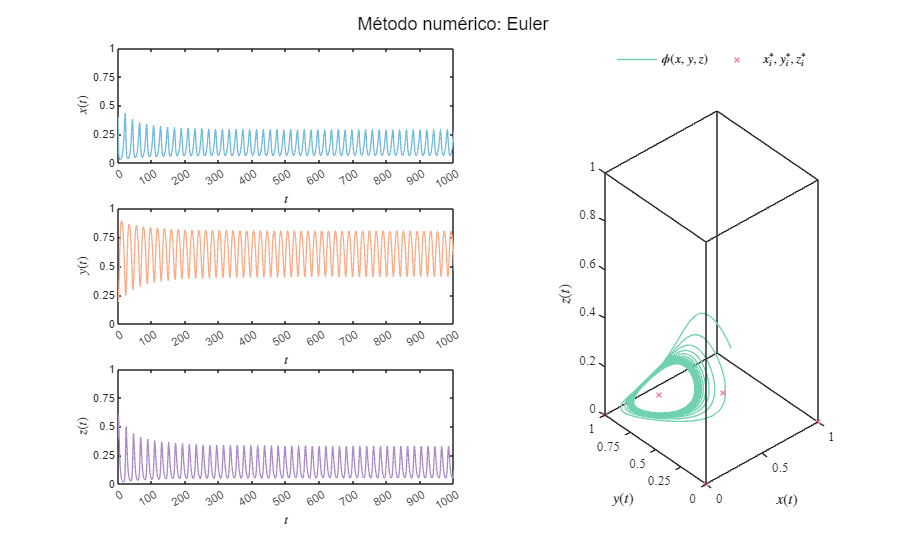

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xe,ye,ze,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Cycle2.pdf'],'ContentType','vector')

### Heun

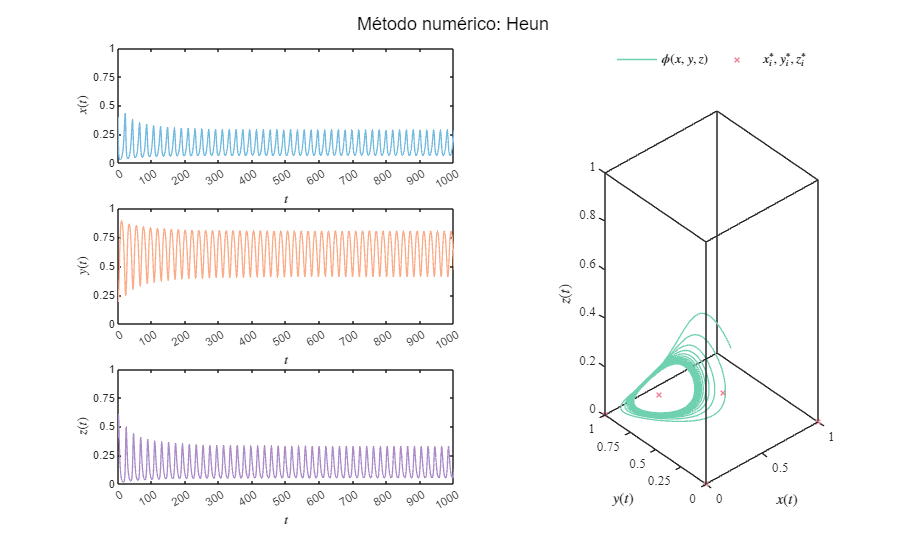

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xh,yh,zh,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Cycle2.pdf'],'ContentType','vector')

### Runge-Kutta

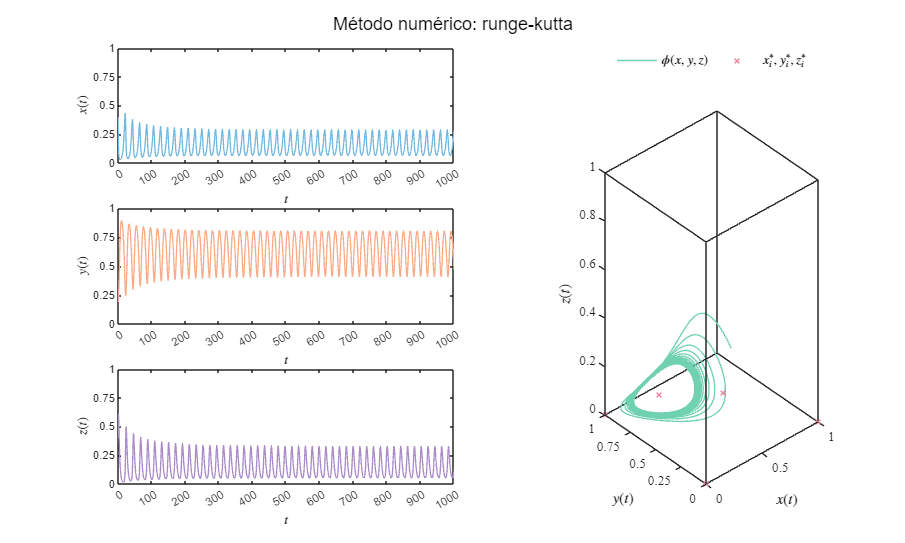

method = 'runge-kutta';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xr,yr,zr,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Cycle2.pdf'],'ContentType','vector')

### Comparación entre soluciones

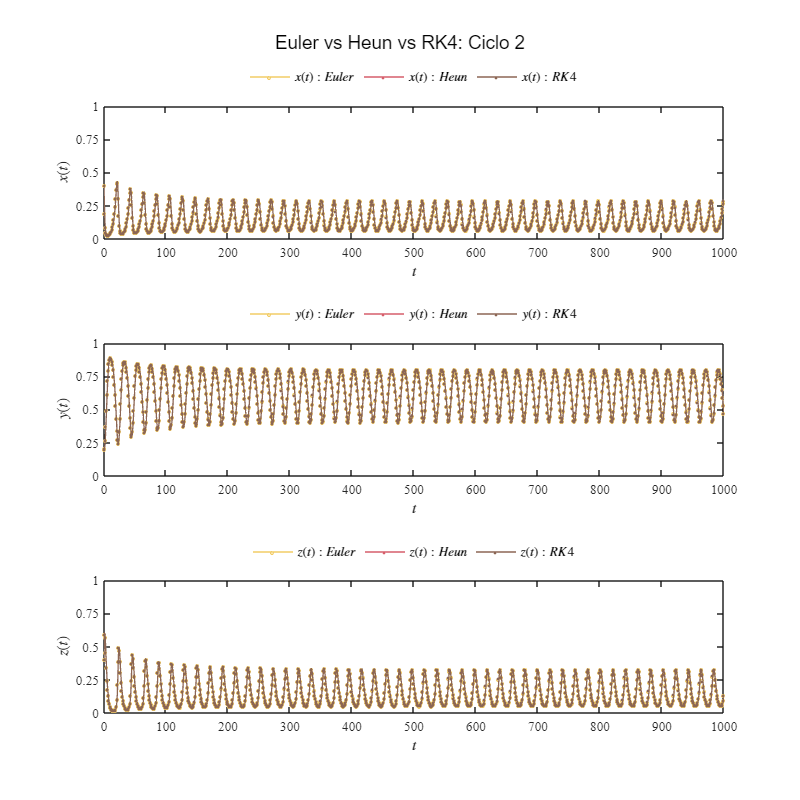

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Ciclo 2');...
    exportgraphics(gcf,'Solutions_Cycle2.pdf','ContentType','vector')

### Error entre soluciones

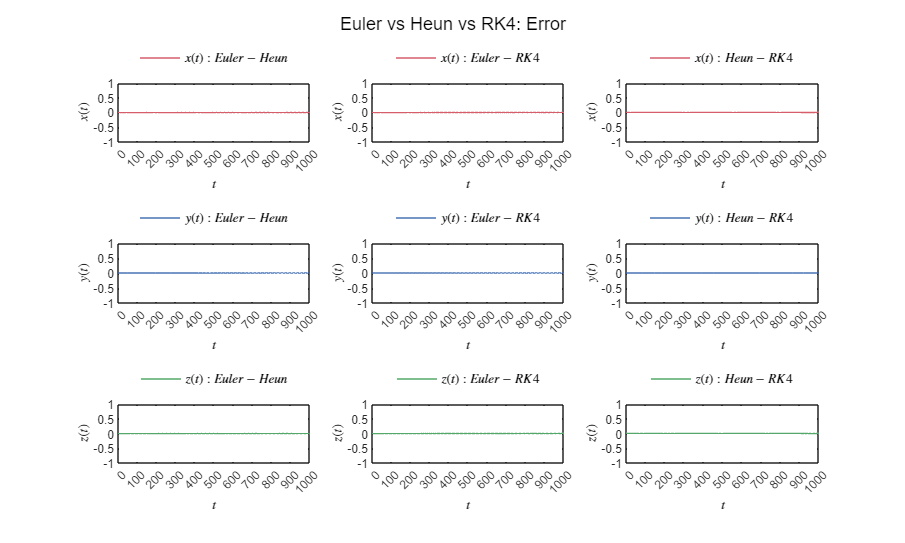

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Error');...
    exportgraphics(gcf,'Error_Cycle2.pdf','ContentType','vector')

## Comparación de métodos numéricos: Punto de Equilibrio

D = getdataa('equilibrium'); f0 = D.f0; par = D.par;
dt = 1E-4; tend = 1000;
rhoi = zeros(round(tend/dt)+1,1);
E = equilibria(par,max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 1.481e-01 , 0.000e+00 , 3.407e-01)
eq2        ( 1.481e-01 , 6.296e-01 , 2.148e-01)
eq3        (-2.000e+00 , 6.000e+00 , 0.000e+00)
eq4        ( 0.000e+00 , 1.000e+00 , 0.000e+00)
eq5        ( 1.000e+00 , 0.000e+00 , 0.000e+00)
eq6        ( 0.000e+00 , 0.000e+00 , 0.000e+00)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         -7.4e-02+5.8e-01i  -7.4e-02-5.8e-01i  +3.8e-01+0.0e+00i  unstable  
eq2         -2.9e-02+4.2e-01i  -2.9e-02-4.2e-01i  -4.7e-01+0.0e+00i  stable    
eq3         -8.0e-01+1.1e+00i  -8.0e-01-1.1e+00i  -5.8e+00+0.0e+00i  stable    
eq4         -6.0e-01+0.0e+00i  +5.0e-01+0.0e+00i  -4.0e-01+0.0e+00i  unstable  
eq5         -1.0e+00+0.0e+00i  -9.0e-01+0.0e+00i  +2.3e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  +6.0e-01+0.0e+00i  +

fprintf('Puntos de equilibrio:\n'); disp(array2table(E))

Puntos de equilibrio:
      E1         E2         E3   
    _______    _______    _______

    0.14815          0    0.34074
    0.14815    0.62963    0.21481
         -2          6          0
          0          1          0
          1          0          0
          0          0          0



### Euler

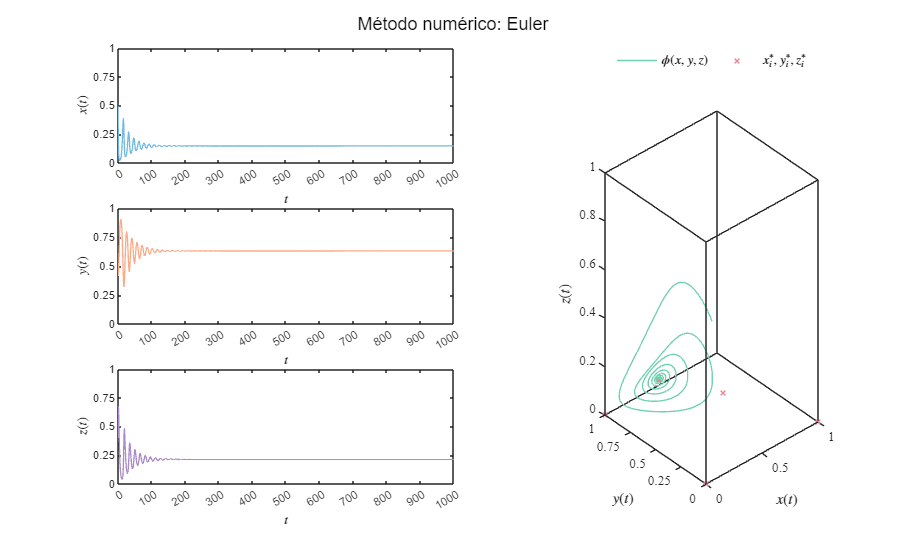

method = 'Euler';
[t,xe,ye,ze] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xe,ye,ze,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Equilibrium.pdf'],'ContentType','vector')

### Heun

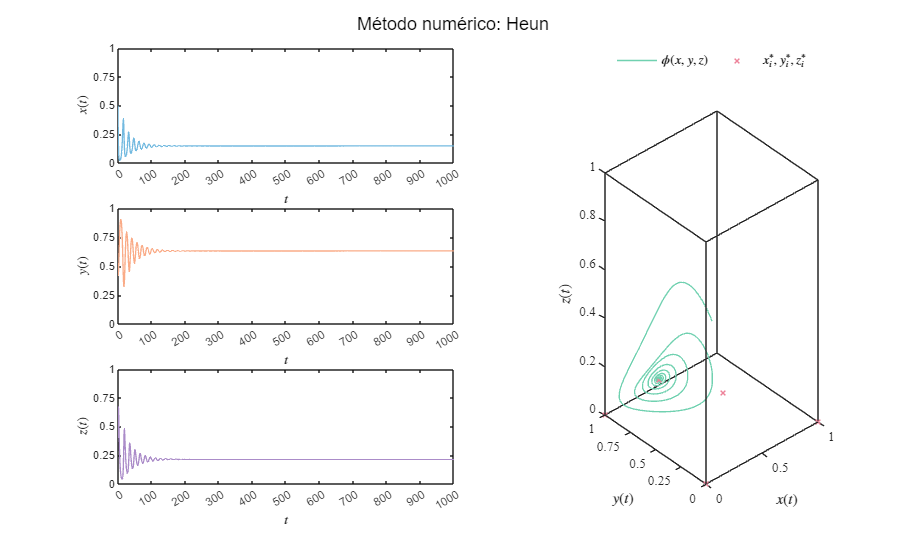

method = 'Heun';
[t,xh,yh,zh] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xh,yh,zh,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Equilibrium.pdf'],'ContentType','vector')

### Runge-Kutta

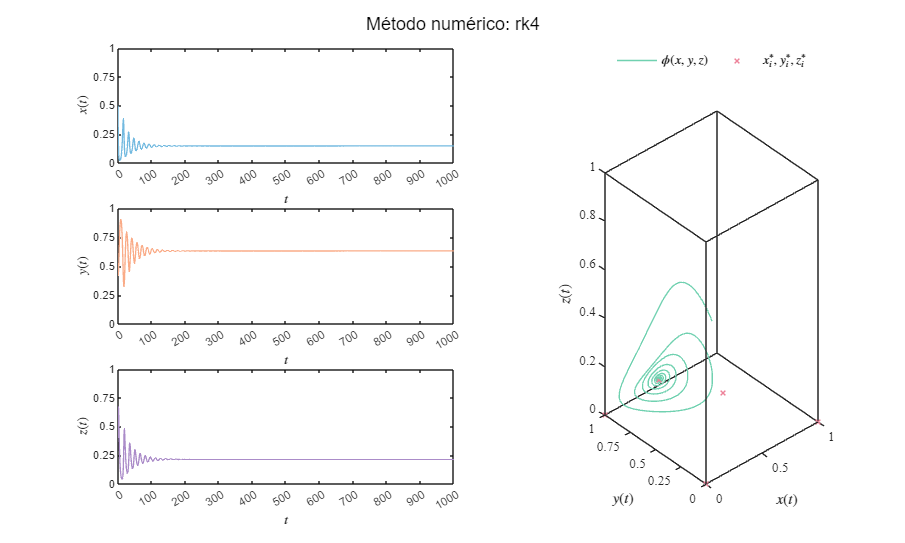

method = 'rk4';
[t,xr,yr,zr] = odesolver(method,f0,par,rhoi,tend,dt);
plotEDOs(t,xr,yr,zr,E); sgtitle(['Método numérico: ', method]);...
    exportgraphics(gcf,[method,'_Equilibrium.pdf'],'ContentType','vector')

### Comparación entre soluciones

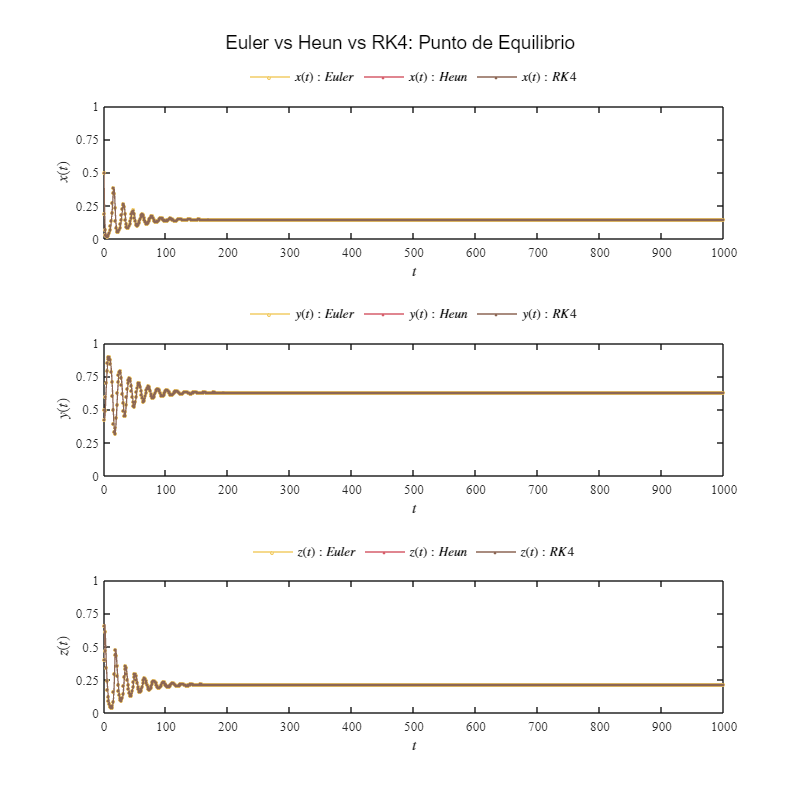

plotdivergence(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Punto de Equilibrio');...
    exportgraphics(gcf,'Solutions_Equilibrium.pdf','ContentType','vector')

### Error entre soluciones

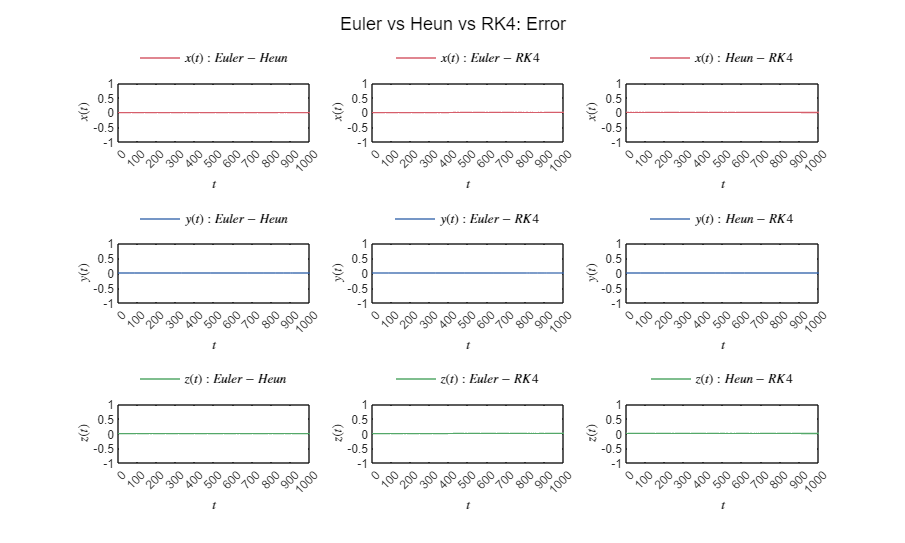

ploterror(t,[xe,xh,xr],[ye,yh,yr],[ze,zh,zr]); sgtitle('Euler vs Heun vs RK4: Error');...
    exportgraphics(gcf,'Error_Equilibrium.pdf','ContentType','vector')

## Condiciones de estabilidad asintótica

### Aplicación del tratamoento: Atractor caotico

% Carga de datos
D = getdataa('chaos'); 
f0 = D.f0; 
par = D.par;
r1 = par(1); 
a12 = par(3); 
a13 = par(4); 
b2 = par(6); 
a21 = par(7); 
d3 = par(10);
CE = (r1 - a12/b2) * a21 / a13 * 1.1; 
if CE == 0
    CE = 0.1;
end
dt = 1e-4; 
tend = 100;
rhoi = ones(round(tend/dt) + 1, 1) * CE;
E = equilibria(par, max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 5.062e-02 , 0.000e+00 , 3.798e-01)
eq2        ( 7.407e-02 , 8.148e-01 , 4.444e-02)
eq3        ( 7.407e-02 , 8.148e-01 , 4.444e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 2.500e-01)
eq5        ( 1.098e+00 , 0.000e+00 ,-3.901e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 2.500e-01)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         -1.6e-01+3.4e-01i  -1.6e-01-3.4e-01i  +5.2e-01+0.0e+00i  unstable  
eq2         +4.5e-01-9.3e-02i  -8.9e-01-4.6e-02i  -3.3e-01-6.2e-01i  unstable  
eq3         +4.5e-01+9.3e-02i  -8.9e-01+4.6e-02i  -3.3e-01+6.2e-01i  unstable  
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -6.2e-01+0.0e+00i  stable    
eq5         -1.2e+00+0.0e+00i  +2.6e+00+0.0e+00i  -1.0e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  +3.8e-01+0.0e+00i  +

method = 'Runge-Kutta';
[t, xr, yr, zr] = odesolver(method, f0, par, rhoi, tend, dt);
plotEDOs(t, xr, yr, zr, E); 

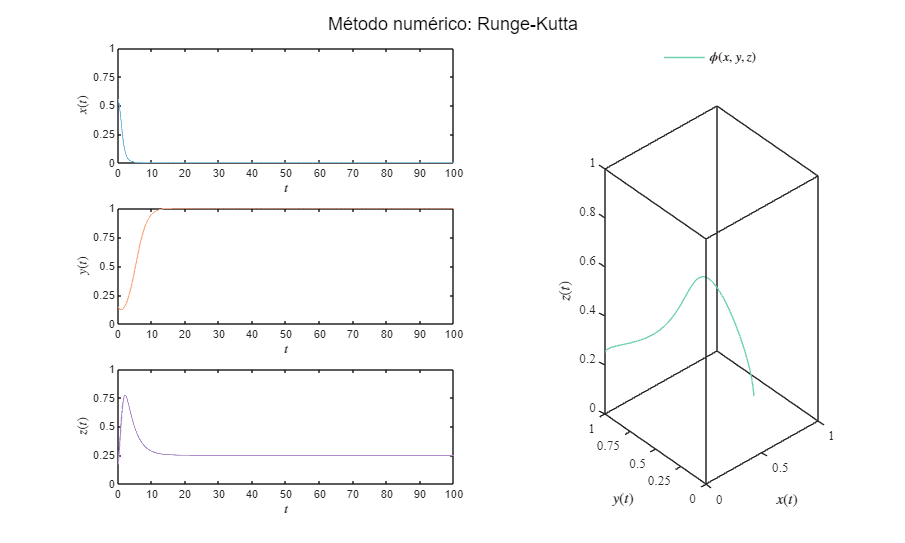

sgtitle(['Método numérico: ', method]);
exportgraphics(gcf, 'rhoi_chaos.pdf', 'ContentType', 'vector');

### Aplicación del tratamoento: Orbita

% Carga de datos
D = getdataa('orbit'); 
f0 = D.f0; 
par = D.par;
r1 = par(1); 
a12 = par(3); 
a13 = par(4); 
b2 = par(6); 
a21 = par(7); 
d3 = par(10);
CE = (r1 - a12/b2) * a21 / a13 * 1.1; 
if CE == 0
    CE = 0.1;
end
dt = 1e-4; 
tend = 100;
rhoi = ones(round(tend/dt) + 1, 1) * CE;
E = equilibria(par, max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 8.161e-02 , 0.000e+00 , 3.674e-01)
eq2        ( 3.407e-02 , 9.148e-01 , 5.704e-02)
eq3        ( 3.407e-02 , 9.148e-01 , 5.704e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 1.650e-01)
eq5        ( 1.067e+00 , 0.000e+00 ,-2.662e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 1.650e-01)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         -1.3e-01+4.5e-01i  -1.3e-01-4.5e-01i  +4.8e-01+0.0e+00i  unstable  
eq2         +2.9e-01-7.8e-02i  -7.8e-01-1.6e-03i  -4.0e-01-5.3e-01i  unstable  
eq3         +2.9e-01+7.8e-02i  -7.8e-01+1.6e-03i  -4.0e-01+5.3e-01i  unstable  
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -3.1e-01+0.0e+00i  stable    
eq5         -1.1e+00+0.0e+00i  +2.5e+00+0.0e+00i  -1.0e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  +5.9e-01+0.0e+00i  +

method = 'Runge-Kutta';
[t, xr, yr, zr] = odesolver(method, f0, par, rhoi, tend, dt);
plotEDOs(t, xr, yr, zr, E); 

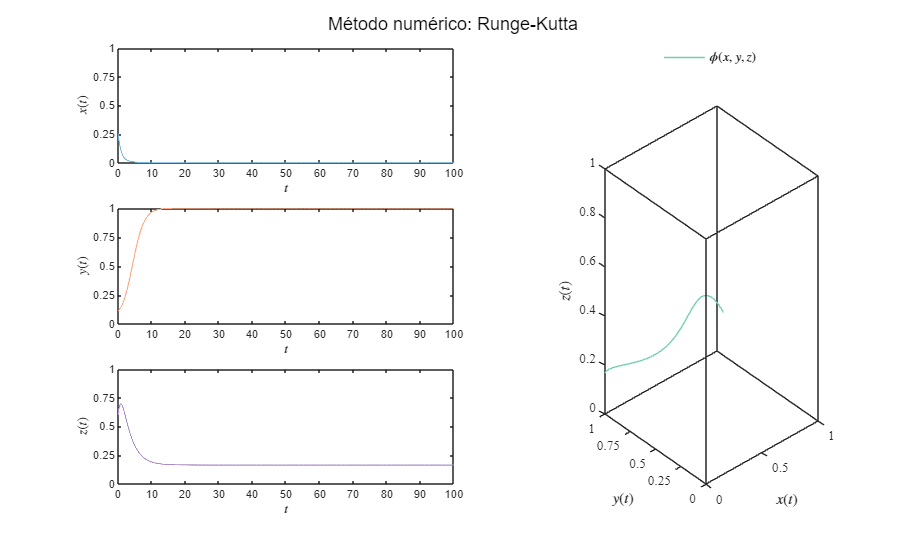

sgtitle(['Método numérico: ', method]);
exportgraphics(gcf, 'rhoi_orbit.pdf', 'ContentType', 'vector');

### Aplicación del tratamoento: Ciclo limite 1

% Carga de datos
D = getdataa('cycle1'); 
f0 = D.f0; 
par = D.par;
r1 = par(1); 
a12 = par(3); 
a13 = par(4); 
b2 = par(6); 
a21 = par(7); 
d3 = par(10);
CE = (r1 - a12/b2) * a21 / a13 * 1.1; 
if CE == 0
    CE = 0.1;
end
dt = 1e-4; 
tend = 100;
rhoi = ones(round(tend/dt) + 1, 1) * CE;
E = equilibria(par, max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        ( 2.304e-02 , 0.000e+00 , 3.908e-01)
eq2        (-2.593e-02 , 1.065e+00 , 6.963e-02)
eq3        (-2.593e-02 , 1.065e+00 , 6.963e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 3.300e-01)
eq5        ( 1.125e+00 , 0.000e+00 ,-5.004e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 3.300e-01)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         -1.8e-01+1.9e-01i  -1.8e-01-1.9e-01i  +5.7e-01+0.0e+00i  unstable  
eq2         +4.0e-01-1.8e-01i  -9.1e-01-5.7e-03i  -5.8e-01-7.9e-01i  unstable  
eq3         +4.0e-01+1.8e-01i  -9.1e-01+5.7e-03i  -5.8e-01+7.9e-01i  unstable  
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -6.2e-01+0.0e+00i  stable    
eq5         -1.2e+00+0.0e+00i  +2.7e+00+0.0e+00i  -1.1e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  +1.7e-01+0.0e+00i  +

method = 'Runge-Kutta';
[t, xr, yr, zr] = odesolver(method, f0, par, rhoi, tend, dt);
plotEDOs(t, xr, yr, zr, E); 

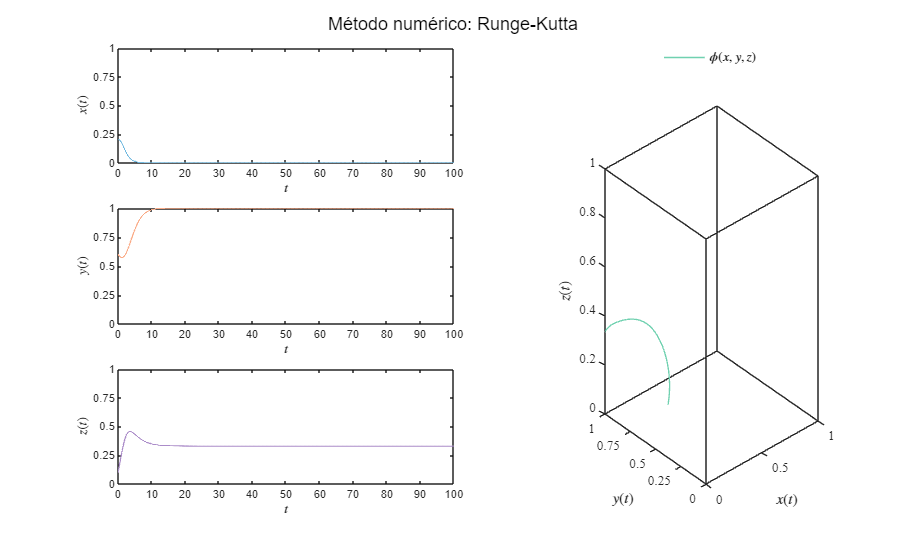

sgtitle(['Método numérico: ', method]);
exportgraphics(gcf, 'rhoi_c1.pdf', 'ContentType', 'vector');

### Aplicación del tratamoento: Ciclo limite 2

% Carga de datos
D = getdataa('cycle2'); 
f0 = D.f0; 
par = D.par;
r1 = par(1); 
a12 = par(3); 
a13 = par(4); 
b2 = par(6); 
a21 = par(7); 
d3 = par(10);
CE = (r1 - a12/b2) * a21 / a13 * 1.1; 
if CE == 0
    CE = 0.1;
end
dt = 1e-4; 
tend = 100;
rhoi = ones(round(tend/dt) + 1, 1) * CE;
E = equilibria(par, max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        (-4.018e-03 , 0.000e+00 , 4.016e-01)
eq2        (-6.878e-02 , 1.172e+00 , 7.593e-02)
eq3        (-6.878e-02 , 1.172e+00 , 7.593e-02)
eq4        ( 0.000e+00 , 1.000e+00 , 4.125e-01)
eq5        ( 1.152e+00 , 0.000e+00 ,-6.087e-02)
eq6        ( 0.000e+00 , 0.000e+00 , 4.125e-01)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         +2.9e-02+0.0e+00i  -4.4e-01+0.0e+00i  +6.1e-01+0.0e+00i  unstable  
eq2         +4.4e-01-2.2e-01i  -9.6e-01-4.3e-03i  -7.0e-01-9.2e-01i  unstable  
eq3         +4.4e-01+2.2e-01i  -9.6e-01+4.3e-03i  -7.0e-01+9.2e-01i  unstable  
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -7.8e-01+0.0e+00i  stable    
eq5         -1.3e+00+0.0e+00i  +2.8e+00+0.0e+00i  -1.1e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  -3.1e-02+0.0e+00i  +

method = 'Runge-Kutta';
[t, xr, yr, zr] = odesolver(method, f0, par, rhoi, tend, dt);
plotEDOs(t, xr, yr, zr, E); 

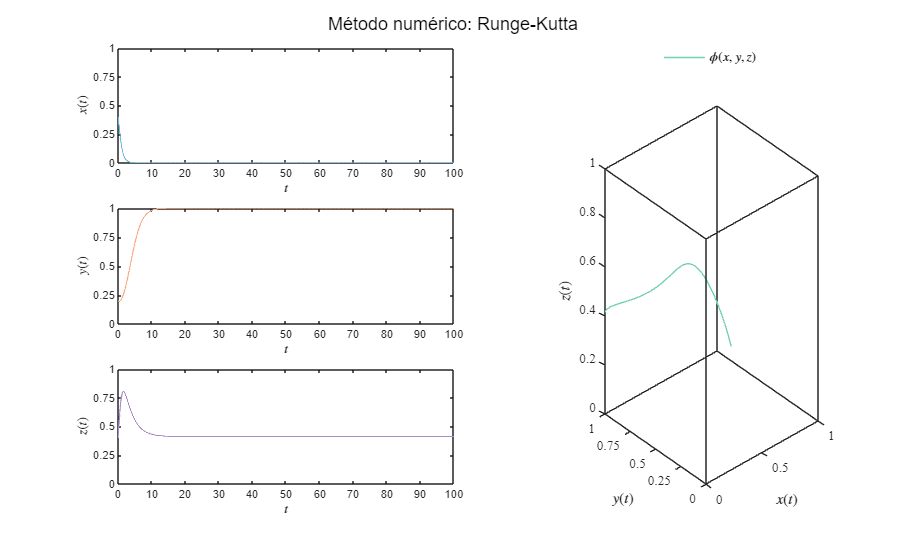

sgtitle(['Método numérico: ', method]);
exportgraphics(gcf, 'rhoi_c2.pdf', 'ContentType', 'vector');

### Aplicación del tratamoento: Punto de equilibrio

% Carga de datos
D = getdataa('equilibrium'); 
f0 = D.f0; 
par = D.par;
r1 = par(1); 
a12 = par(3); 
a13 = par(4); 
b2 = par(6); 
a21 = par(7); 
d3 = par(10);
CE = (r1 - a12/b2) * a21 / a13 * 1.1; 
if CE == 0
    CE = 0.1;
end
dt = 1e-4; 
tend = 100;
rhoi = ones(round(tend/dt) + 1, 1) * CE;
E = equilibria(par, max(rhoi));

Equilibria  |  x*       |  y*       |  z*      |
-------------------------------------------------
eq1        (-1.238e-01 , 0.000e+00 , 4.495e-01)
eq2        (-9.259e-01 , 3.315e+00 , 1.074e-01)
eq3        (-9.259e-01 , 3.315e+00 , 1.074e-01)
eq4        ( 0.000e+00 , 1.000e+00 , 8.250e-01)
eq5        ( 1.272e+00 , 0.000e+00 ,-1.088e-01)
eq6        ( 0.000e+00 , 0.000e+00 , 8.250e-01)
Equilibria |    lambda 1      |    lambda 2      |    lambda 3     | stability |
--------------------------------------------------------------------------------
eq1         +4.4e-01+0.0e+00i  -1.1e+00+0.0e+00i  +7.9e-01+0.0e+00i  unstable  
eq2         +6.5e-02-2.1e-01i  -1.0e+00+5.8e-02i  -3.0e+00-6.9e-01i  unstable  
eq3         +6.5e-02+2.1e-01i  -1.0e+00-5.8e-02i  -3.0e+00+6.9e-01i  unstable  
eq4         -4.0e-01+0.0e+00i  -6.0e-01+0.0e+00i  -1.6e+00+0.0e+00i  stable    
eq5         -1.5e+00+0.0e+00i  +3.2e+00+0.0e+00i  -1.3e+00+0.0e+00i  unstable  
eq6         -4.0e-01+0.0e+00i  -1.1e+00+0.0e+00i  +

method = 'Runge-Kutta';
[t, xr, yr, zr] = odesolver(method, f0, par, rhoi, tend, dt);
plotEDOs(t, xr, yr, zr, E); 

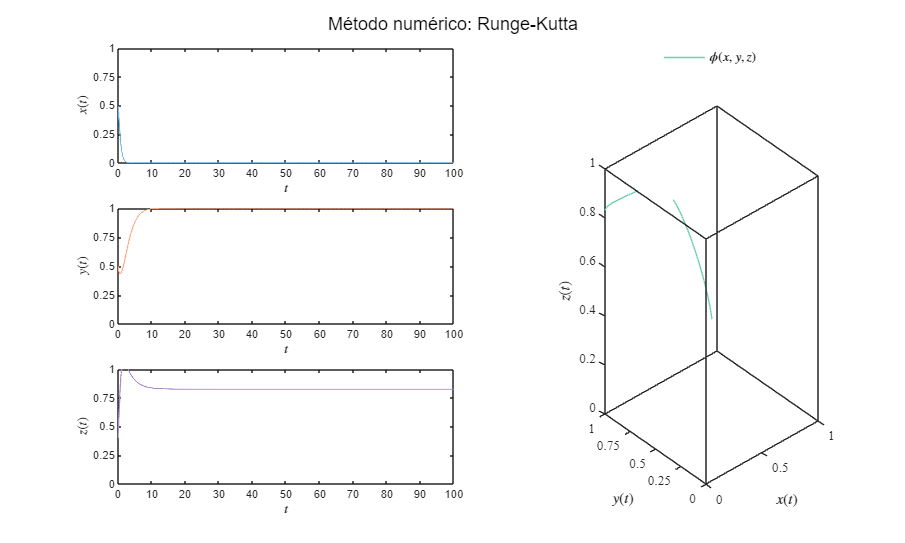

sgtitle(['Método numérico: ', method]);
exportgraphics(gcf, 'rhoi_eq.pdf', 'ContentType', 'vector');

## Funciones

### Parámetros y condiciones iniciales

function D = getdataa(dynamics)
    r1 = 1; b1 = 1; a13 = 2.5;
    r2 = 0.6; b2 = 1; a21 = 1.5;
    r3 = 3; a31 = 0.3; d3 = 0.4;

    switch dynamics
        case "chaos";       a12 = 1;    f0 = [0.555, 0.148, 0.172];
        case "orbit";       a12 = 0.9;  f0 = [0.254781, 0.115167, 0.600527];
        case "cycle1";      a12 = 0.8;  f0 = [0.2, 0.6, 0.1];
        case "cycle2";      a12 = 0.75; f0 = [0.4, 0.2, 0.4];
        case "equilibrium"; a12 = 0.5;  f0 = [0.5, 0.5, 0.4];
    end
    D.par = [r1, b1, a12, a13, r2, b2, a21, r3, a31, d3];
    D.f0 = f0;
end




### Métodos numéricos


function [t_out, x, y, z] = odesolver(method, f0, par, rhoi, tend, dt)
    n = round(tend/dt);
    t = (0:dt:tend);
    xv = zeros(length(t),1); yv = zeros(length(t),1); zv = zeros(length(t),1);
    xv(1) = f0(1); yv(1) = f0(2); zv(1) = f0(3);
    
    % Parámetros locales para velocidad
    r1=par(1); b1=par(2); a12=par(3); a13=par(4);
    r2=par(5); b2=par(6); a21=par(7);
    r3=par(8); a31=par(9); d3=par(10);

    f = @(x,y,z,r) [r1*x*(1-b1*x)-a12*x*y-a13*x*z; 
                    r2*y*(1-b2*y)-a21*x*y; 
                    (r3-a31)*x*z-d3*z+r];

    for i = 1:n
        curr_rho = rhoi(i);
        switch lower(method)
            case 'euler'
                k1 = f(xv(i), yv(i), zv(i), curr_rho);
                xv(i+1) = xv(i) + dt*k1(1);
                yv(i+1) = yv(i) + dt*k1(2);
                zv(i+1) = zv(i) + dt*k1(3);
            case 'heun'
                k1 = f(xv(i), yv(i), zv(i), curr_rho);
                xp = xv(i) + dt*k1(1); yp = yv(i) + dt*k1(2); zp = zv(i) + dt*k1(3);
                k2 = f(xp, yp, zp, curr_rho);
                xv(i+1) = xv(i) + (dt/2)*(k1(1)+k2(1));
                yv(i+1) = yv(i) + (dt/2)*(k1(2)+k2(2));
                zv(i+1) = zv(i) + (dt/2)*(k1(3)+k2(3));
            case {'rk4', 'runge-kutta'}
                k1 = f(xv(i), yv(i), zv(i), curr_rho);
                k2 = f(xv(i)+dt/2*k1(1), yv(i)+dt/2*k1(2), zv(i)+dt/2*k1(3), curr_rho);
                k3 = f(xv(i)+dt/2*k2(1), yv(i)+dt/2*k2(2), zv(i)+dt/2*k2(3), curr_rho);
                k4 = f(xv(i)+dt*k3(1), yv(i)+dt*k3(2), zv(i)+dt*k3(3), curr_rho);
                xv(i+1) = xv(i) + (dt/6)*(k1(1)+2*k2(1)+2*k3(1)+k4(1));
                yv(i+1) = yv(i) + (dt/6)*(k1(2)+2*k2(2)+2*k3(2)+k4(2));
                zv(i+1) = zv(i) + (dt/6)*(k1(3)+2*k2(3)+2*k3(3)+k4(3));
        end
    end
    % Muestreo para no saturar memoria/gráficos (h=10 como en tu código)
    idx = 1:100:length(t);
    t_out = t(idx)'; x = xv(idx); y = yv(idx); z = zv(idx);
end

## Soluciones y espacio de fase

function plotEDOs(t,x,y,z,E)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1 1 25 15])
    FS = 10;
    b = [0.28, 0.45, 0.70]; % Azul suave
    n = [0.87, 0.52, 0.32]; % Naranja apagado
    v = [0.33, 0.66, 0.41]; % Verde salvia
    r = [0.84, 0.37, 0.42]; % Rojo coral / Rosa viejo
    p = [0.51, 0.44, 0.69]; % Púrpura lavanda
    m = [0.55, 0.40, 0.33]; % Marrón terracota
    a  = [0.45, 0.73, 0.88]; % Azul cielo
    d  = [0.98, 0.67, 0.53]; % Naranja pastel / Durazno
    vm  = [0.44, 0.82, 0.69]; % Verde menta
    ro  = [0.93, 0.51, 0.60]; % Rosa claro
    l  = [0.67, 0.55, 0.79]; % Lila suave
    am = [0.95, 0.80, 0.40]; % Amarillo mostaza suave
        
    subplot(3,6,[1 2 3]); box on; hold on;
    plot(t,x,'-','LineWidth',1,'Color',a)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)

    subplot(3,6,[7 8 9]); box on; hold on;
    plot(t,y,'-','LineWidth',1,'Color',d)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)


    subplot(3,6,[13 14 15]); box on; hold on;
    plot(t,z,'-','LineWidth',1,'Color',l)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)


    subplot(3,6,[5 6 11 12 17 18]); hold on; grid off; box on; view([-42 21])
    ax = gca; ax.BoxStyle = 'full';
    % Filtrar equilibria válidos
    idx = all(isreal(E),2) & all(~isnan(E),2) & all(~isinf(E),2);
    E = E(idx,:);
    
    % (opcional) solo biológicamente factibles
    E = E(all(E>=0,2),:);
    plot3(x,y,z,'-','LineWidth',1,'Color',vm)
    % Filtrar antes de graficar
    idx = all(isreal(E),2) & all(~isnan(E),2) & all(~isinf(E),2);
    Eplot = E(idx,:);
    Eplot = Eplot(all(Eplot>=0,2),:); % opcional
    
    if ~isempty(Eplot)
        plot3(Eplot(:,1),Eplot(:,2),Eplot(:,3),'x',...
            'MarkerSize',5,'LineWidth',1,'Color',ro);
    end
    L = legend('$\phi(x,y,z)$','$x^*_i,y^*_i,z^*_i$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside','Box','Off','Orientation','Horizontal')
    xlim([0 1]); yticks(0:0.25:1)
    ylim([0 1]); yticks(0:0.25:1)
    zlim([0 1]); yticks(0:0.25:1)
    xlabel('$x(t)$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    zlabel('$z(t)$','Interpreter','latex','FontSize',FS)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
end

function plotdivergence(t,x,y,z)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1 1 25 25])
    FS = 10;
    b = [0.28, 0.45, 0.70]; % Azul suave
    n = [0.87, 0.52, 0.32]; % Naranja apagado
    v = [0.33, 0.66, 0.41]; % Verde salvia
    r = [0.84, 0.37, 0.42]; % Rojo coral / Rosa viejo
    p = [0.51, 0.44, 0.69]; % Púrpura lavanda
    m = [0.55, 0.40, 0.33]; % Marrón terracota
    a  = [0.45, 0.73, 0.88]; % Azul cielo
    d  = [0.98, 0.67, 0.53]; % Naranja pastel / Durazno
    vm  = [0.44, 0.82, 0.69]; % Verde menta
    ro  = [0.93, 0.51, 0.60]; % Rosa claro
    l  = [0.67, 0.55, 0.79]; % Lila suave
    am = [0.95, 0.80, 0.40]; % Amarillo mostaza suave
    colororder([am;r;m]);

    subplot(3,1,1); box on; hold on; grid off;
    plot(t,x(:,1),'-o',t,x(:,2),'-+',t,x(:,3),'-x',...
        'LineWidth',1,'MarkerSize',2,'MarkerIndices',1:100:length(t));
    L = legend('$x(t): Euler$', '$x(t): Heun$', '$x(t): RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside','Box','Off','Orientation','Horizontal')
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,1,2); box on; hold on; grid off;
    plot(t,y(:,1),'-o',t,y(:,2),'-+',t,y(:,3),'-x',...
        'LineWidth',1,'MarkerSize',2,'MarkerIndices',1:100:length(t));
    L = legend('$y(t): Euler$', '$y(t): Heun$', '$y(t): RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside','Box','Off','Orientation','Horizontal')
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,1,3); box on; hold on; grid off;
    plot(t,z(:,1),'-o',t,z(:,2),'-+',t,z(:,3),'-x',...
        'LineWidth',1,'MarkerSize',2,'MarkerIndices',1:100:length(t));
    L = legend('$z(t): Euler$', '$z(t): Heun$', '$z(t): RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside','Box','Off','Orientation','Horizontal')
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([0 1]); yticks(0:0.25:1)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

function ploterror(t,x,y,z)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1 1 25 15])
    FS = 10;
    b = [0.28, 0.45, 0.70]; % Azul suave
    n = [0.87, 0.52, 0.32]; % Naranja apagado
    v = [0.33, 0.66, 0.41]; % Verde salvia
    r = [0.84, 0.37, 0.42]; % Rojo coral / Rosa viejo
    p = [0.51, 0.44, 0.69]; % Púrpura lavanda
    m = [0.55, 0.40, 0.33]; % Marrón terracota
    a  = [0.45, 0.73, 0.88]; % Azul cielo
    d  = [0.98, 0.67, 0.53]; % Naranja pastel / Durazno
    vm  = [0.44, 0.82, 0.69]; % Verde menta
    ro  = [0.93, 0.51, 0.60]; % Rosa claro
    l  = [0.67, 0.55, 0.79]; % Lila suave
    am = [0.95, 0.80, 0.40]; % Amarillo mostaza suave
        
    subplot(3,3,1); box on; hold on;
    plot(t,x(:,1) - x(:,2),'-','LineWidth',1,'Color',r)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$x(t): Euler - Heun$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)

    subplot(3,3,2); box on; hold on;
    plot(t,x(:,1) - x(:,3),'-','LineWidth',1,'Color',r)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$x(t): Euler - RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)


    subplot(3,3,3); box on; hold on;
    plot(t,x(:,2) - x(:,3),'-','LineWidth',1,'Color',r)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$x(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$x(t): Heun - RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)


    subplot(3,3,4); box on; hold on;
    plot(t,y(:,1) - y(:,2),'-','LineWidth',1,'Color',b)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$y(t): Euler - Heun$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)

    subplot(3,3,5); box on; hold on;
    plot(t,y(:,1) - y(:,3),'-','LineWidth',1,'Color',b)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$y(t): Euler - RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)


    subplot(3,3,6); box on; hold on;
    plot(t,x(:,2) - x(:,3),'-','LineWidth',1,'Color',b)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$y(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$y(t): Heun - RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)

    subplot(3,3,7); box on; hold on;
    plot(t,z(:,1) - z(:,2),'-','LineWidth',1,'Color',v)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$z(t): Euler - Heun$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)

    subplot(3,3,8); box on; hold on;
    plot(t,z(:,1) - z(:,3),'-','LineWidth',1,'Color',v)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$z(t): Euler - RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)


    subplot(3,3,9); box on; hold on;
    plot(t,z(:,2) - z(:,3),'-','LineWidth',1,'Color',v)
    xlabel('$t$','Interpreter','latex','FontSize',FS)
    ylabel('$z(t)$','Interpreter','latex','FontSize',FS)
    L = legend('$z(t): Heun - RK4$');
    set(L,'Interpreter','Latex','Fontsize',FS,'Location','NorthOutside',...
        'Box','Off','Orientation','Horizontal')
    xlim([0 inf]); xticks(0:t(end)/10:t(end))
    ylim([-1 1]); yticks(-1:0.5:1)
    
end


## Equilibrios

function E = equilibria(par,rhoi)
    r1 = par(1); b1 = par(2); a12 = par(3); a13 = par(4);
    r2 = par(5); b2 = par(6); a21 = par(7);
    r3 = par(8); a31 = par(9); d3 = par(10);
    
    e1 = [(r1 - (a13*(a31*r1 - r1*r3 - sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rhoi*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rhoi*b1*r3 + r1*r3^2)) + b1*d3*r1))/(2*(a13*a31 - a13*r3)))/(b1*r1); 0; (a31*r1 - r1*r3 - sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rhoi*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rhoi*b1*r3 + r1*r3^2)) + b1*d3*r1)/(2*(a13*a31 - a13*r3))];
    e2 = [(r2*(a12 - b2*r1))/(a12*a21 - b1*b2*r1*r2) - (sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (a21*r1 - b1*r1*r2)/(a12*a21 - b1*b2*r1*r2) + (a21*(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); -(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))];
    e3 = [(r2*(a12 - b2*r1))/(a12*a21 - b1*b2*r1*r2) + (sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (a21*r1 - b1*r1*r2)/(a12*a21 - b1*b2*r1*r2) - (a21*(sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3)); (sqrt(a12^2*a21^2*d3^2 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + a12^2*a31^2*r2^2 - 2*a12^2*a31*r2^2*r3 + a12^2*r2^2*r3^2 - 2*a12*a21*a31*b2*d3*r1*r2 + 4*a13*rhoi*a12*a21*a31*b2*r2 - 2*a12*a21*b1*b2*d3^2*r1*r2 + 2*a12*a21*b2*d3*r1*r2*r3 - 4*a13*rhoi*a12*a21*b2*r2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 2*a12*b2*r1*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 4*a13*rhoi*a31*b1*b2^2*r1*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*rhoi*b1*b2^2*r1*r2^2*r3 + b2^2*r1^2*r2^2*r3^2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))];
    e4 = [0; 1/b2; rhoi/d3];
    e5 = [(r1 - (a13*(a31*r1 - r1*r3 + sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rhoi*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rhoi*b1*r3 + r1*r3^2)) + b1*d3*r1))/(2*(a13*a31 - a13*r3)))/(b1*r1); sym(0); (a31*r1 - r1*r3 + sqrt(r1*(r1*a31^2 + 2*r1*a31*b1*d3 - 4*a13*rhoi*a31*b1 - 2*r1*a31*r3 + r1*b1^2*d3^2 - 2*r1*b1*d3*r3 + 4*a13*rhoi*b1*r3 + r1*r3^2)) + b1*d3*r1)/(2*(a13*a31 - a13*r3))];
    e6 = [0; 0; rhoi/d3];
    E = [e1,e2,e3,e4,e5,e6]; E = double(E)'; E(E>-1e-12 & E<1e-12) = 0;
    names = {'eq1';'eq2';'eq3';'eq4';'eq5';'eq6'};
    fprintf('%-11s | %-9s | %-9s | %-9s|\n','Equilibria', ' x*', ' y*', ' z*');
    fprintf('-------------------------------------------------\n');
    for i = 1:length(E)
        fprintf('%-10s (%10.3e ,%10.3e ,%10.3e)\n', names{i}, E(i,1), E(i,2), E(i,3));
    end

    x = E(:,1); y = E(:,2); z = E(:,3); lambda = zeros(length(E),3); stability = cell(length(E),1);
    for i = 1:length(E)
        J = [- a12*y(i) - a13*z(i) - r1*(b1*x(i) - 1) - b1*r1*x(i), -a12*x(i), -a13*x(i);
             -a21*y(i), - a21*x(i) - r2*(b2*y(i) - 1) - b2*r2*y(i), 0; 
             -z(i)*(a31 - r3), 0, - d3 - x(i)*(a31 - r3)];
        lambda(i,:) = eig(J);
        rp = real(lambda(i,:));
        if all(rp < 0)
            stability{i,1} = 'stable';
        elseif any(rp > 0)
            stability{i,1} = 'unstable';
        else
            stability{i,1} = 'unidentified';
        end
    end
    
    fprintf('%-10s | %-16s | %-16s | %-16s| %-10s|\n',...
        'Equilibria', '   lambda 1', '   lambda 2', '   lambda 3', 'stability');
    fprintf('--------------------------------------------------------------------------------\n');
    for i = 1:length(E)
        fprintf('%-10s  %+.1e%+.1ei  %+.1e%+.1ei  %+.1e%+.1ei  %-10s\n', names{i},...
            real(lambda(i,1)),imag(lambda(i,1)),...
            real(lambda(i,2)),imag(lambda(i,2)),...
            real(lambda(i,3)),imag(lambda(i,3)), stability{i});
    end
end